# Dispersing Prism

The following MATLAB script uses geometrical optics to visualize a light ray inciding on a glass prism.

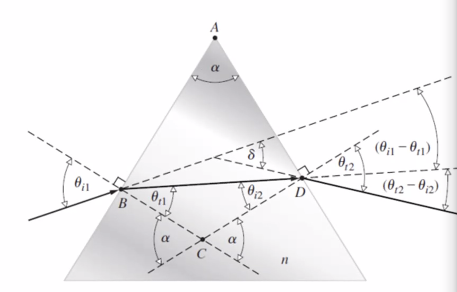

clc; clf; clear;

## Define General Parameters

n_air = 1;      %Refraction index
n_glass = 1.52; %Refraction index

## Define Equilateral Triangle

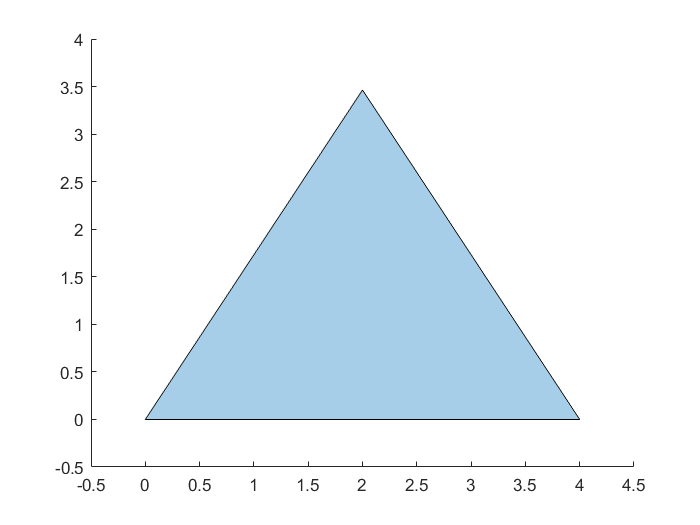

L = 4;          %Leneght of sides 
x1 = [0,L/2];     
y1 = [0, L*sqrt(3)/2];

%Define slope of side
m1 = (y1(2)-y1(1))/(x1(2)-x1(1));

%Equation of side 1
side1 = @(x) m1*x;

%Apex angle (alpha)
alpha = acos((L/2)/L);

% Plot the prism
p = nsidedpoly(3, 'Center', [x1(2) ,L*sqrt(3)/6], 'SideLength', 4);
plot(p)
hold on

% plot([0:L/2],side1([0:L/2]),"b")

## Define Incident Ray

In this section, we calculate the incident angle ($\theta_{i1]$) and plot the incident ray. 

Let: 

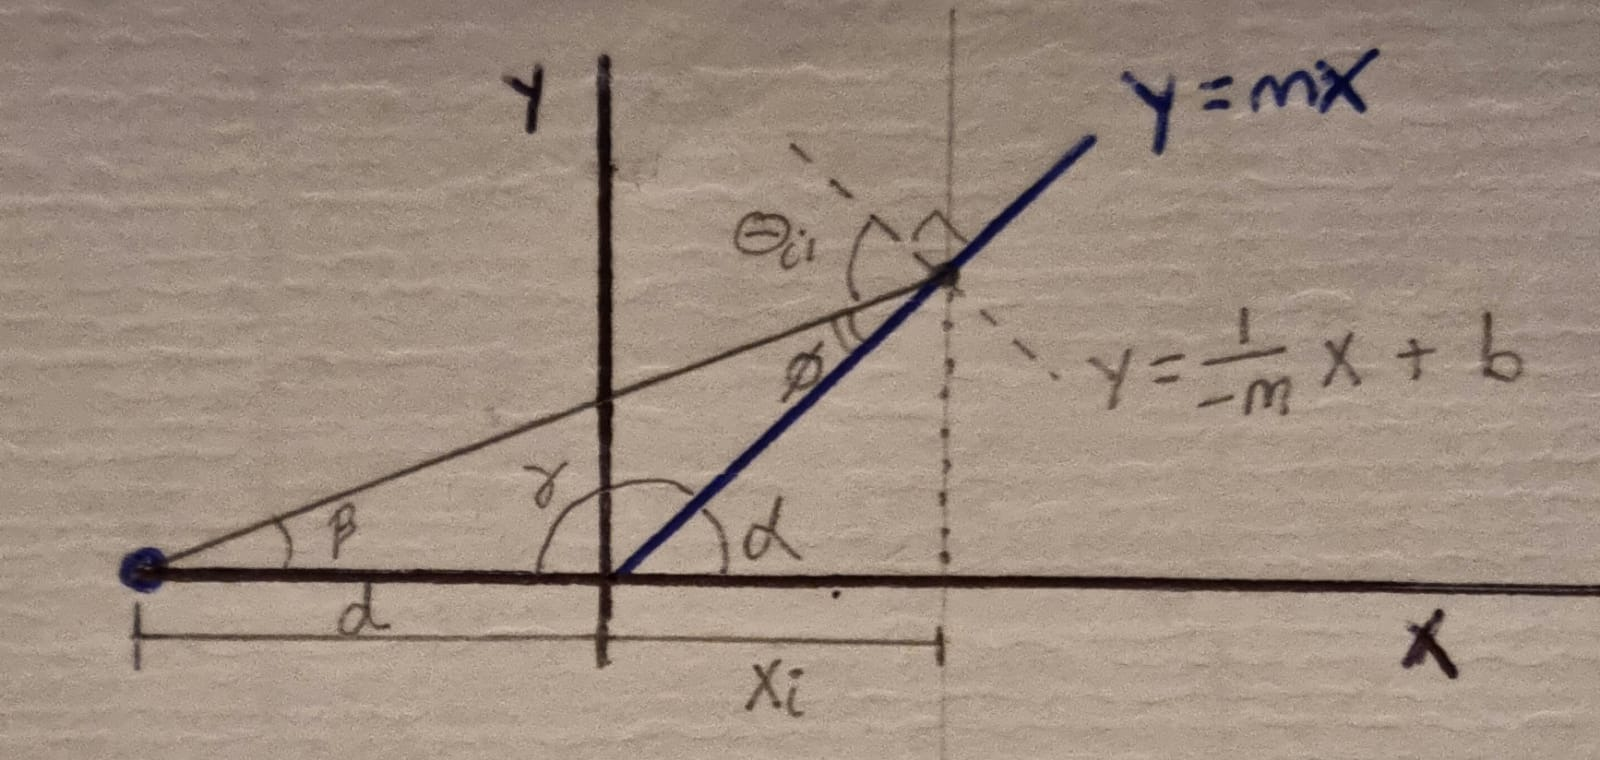

%Define general parameters
d = -10;     %Distance to source.
xi = 0.9;    %Incident x-coor.

%Calculate internal angles
beta = atan(side1(xi)/(abs(d)+xi));
gamma = pi - alpha;
phi = pi - gamma - beta; 

%Calculate incident angle (theta_i1)
theta_i1 = pi/2 - phi; 

%Plot system
plot([d,xi],[0,side1(xi)])
axis equal

Using Snell law, calculate all the angles. Remember, these angles are measured with respect to the normal. 

% Calculate first transmited angle.
theta_t1 = asin(n_air/n_glass *sin(theta_i1));

% Calculate second incident angle
w = (2*pi - 2*alpha)/2;
theta_i2 = pi - theta_t1 - w;

% Calculate second transmited angle.
thet_t2 = asin(n_glass * sin(theta_i2)/n_air);

To visualize the first refracted ray, we need to find the coodinates for the point **R(**$x_{\textrm{i2}} ,y_{\textrm{i2}}$**). **

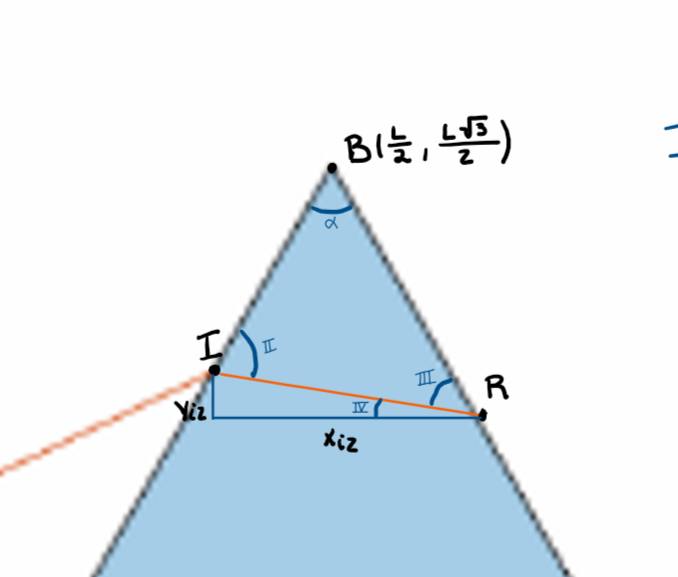

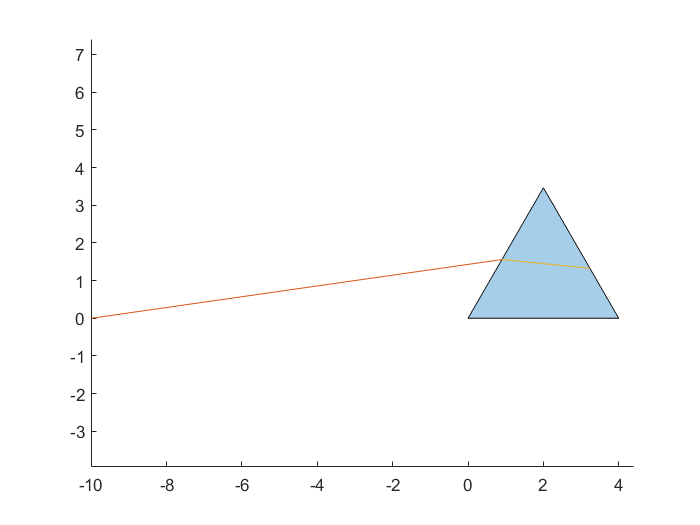

%Side of triangle IBR
IB = sqrt((L/2 - xi)^2 + (L*sqrt(3)/2 - side1(xi))^2);

%Calculate the angles for IBR
II = pi/2 - theta_t1;
III = pi - alpha - II;
IV = alpha - III; 

%Calculate incident ray IR
IR = sin(alpha)/sin(III) * IB; 

%Calculate coordinates for R
yi2 = side1(xi) - sin(IV)*IR;
xi2= xi + cos(IV)*IR;

%Visualize Ray
plot([xi,xi2],[side1(xi),yi2])

Finally, to visualize the last refracted ray, we define a random coordinate $x_{\textrm{r3}}$ and form the right angled triangle. 

Let: 

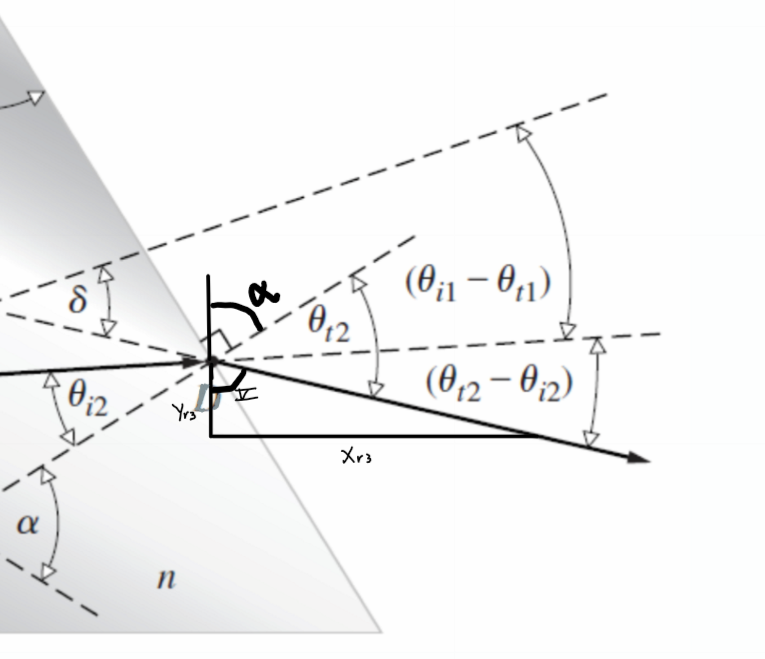

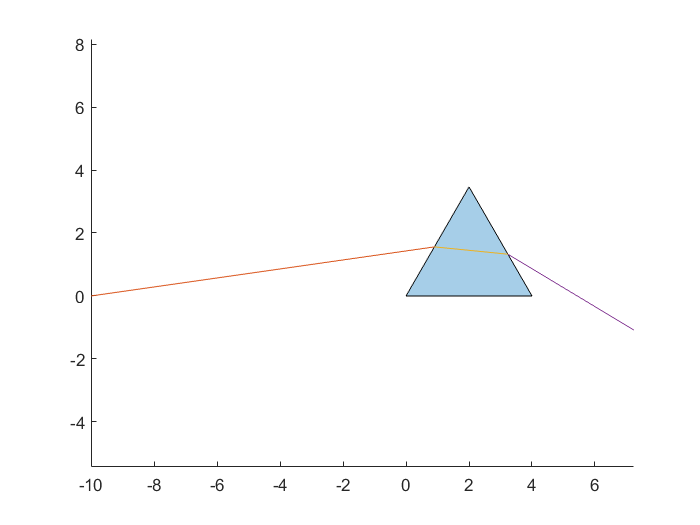

%Derfine angle
V = pi - alpha - thet_t2; 

%Define parameters of visualization
xr3 = 4; 
yr3 = xr3/tan(V);

%Visualize Ray
plot([xi2,xi2+xr3],[yi2,yi2-yr3])

## Visualization

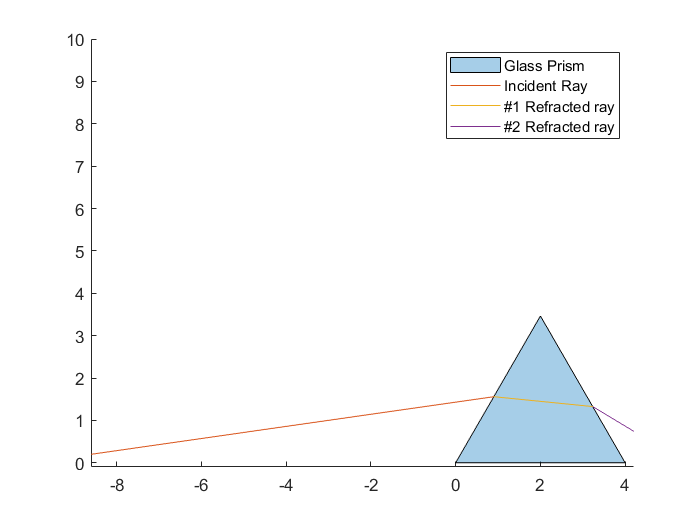

ylim([-0.1, 10])
legend("Glass Prism","Incident Ray", "#1 Refracted ray","#2 Refracted ray")